**Computer Exercise 4.4.1**

The following program will analyze the interpolation of the function $f(x) = (x^2 +1)^{-1}$ by using 20 equally space nodes on the interval $[-5, 5]$. The interpolated values will then be tabulated and plotted to assist in analysis. 

f = @(x) (x.^2 +1).^(-1); %initiate function
nodes = linspace(-5, 5, 21);
data = f(nodes);
xvals = linspace(-5, 5, 41); %x values to evaluate functions
yvals1 = interp_func(xvals, nodes, data); %p(x) evaluated at xvals
yvals2 = f(xvals); %f(x) evaluated at xvals
error = abs(yvals1 - yvals2);
table1 = table(xvals', yvals1', yvals2', error', ...
    'VariableNames', {'x', 'p(x)', 'f(x)', 'error'});
disp(table1)

      x             p(x)                  f(x)                  error       
    _____    __________________    __________________    ___________________

       -5    0.0384615384615385    0.0384615384615385                      0
    -4.75     -39.9524490330417    0.0424403183023873       39.9948893513441
     -4.5    0.0470588235294118    0.0470588235294118                      0
    -4.25      3.45495779986408    0.0524590163934426       3.40249878347064
       -4    0.0588235294117647    0.0588235294117647                      0
    -3.75    -0.447051960708839    0.0663900414937759      0.513442002202615
     -3.5    0.0754716981132075    0.0754716981132075                      0
    -3.25     0.202422615704561    0.0864864864864865      0.115936129218074
       -3                   0.1                   0.1                      0
    -2.75    0.0

We get alternating errors of zero in our table because the interpolated polynomial points at the nodes were based off of the function itself since we needed "data" points to perform interpolation.

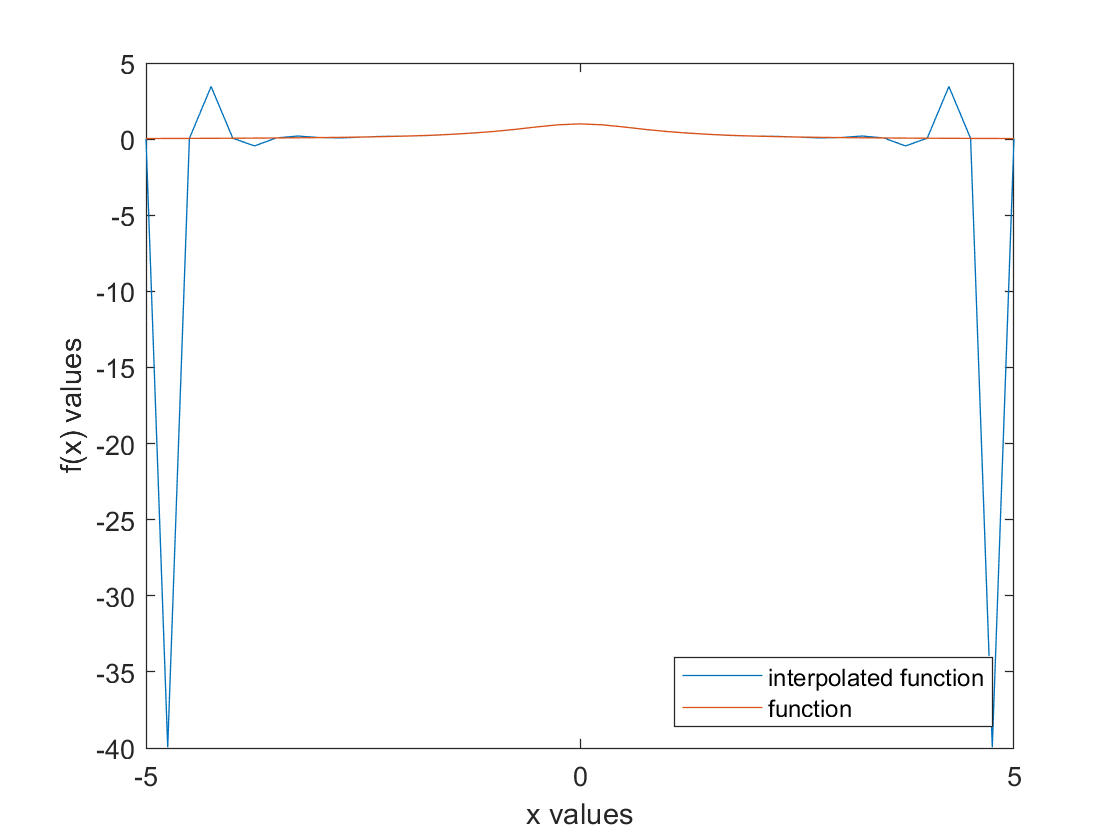

plot(xvals, yvals1, xvals, yvals2)
xlabel('x values')
ylabel('f(x) values')
legend('interpolated function', 'function', "Location","southeast")

From the plot, we can see that the interpolation works great near zero, but as x approaches the end points, the errors become larger and we begin to see oscillation.

function sum = interp_func(x, nodes, data) %Lagrange Interpolation
    sum = 0;
    for i = 1:length(nodes)
        prod = 1;
        for j = 1:length(nodes)
            if j ~= i
                prod = prod .* ( (x - nodes(j))./(nodes(i) - nodes(j)) );
            end
        end
        sum = sum + data(i).*prod;
    end
end